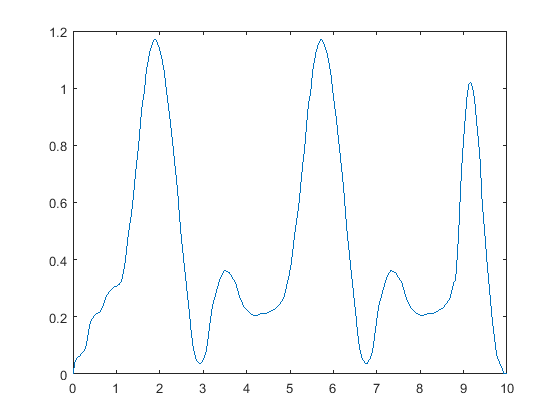

load exp2Msetup.mat sm_path1

t_smpath = sm_path1.Time;
Ts = 0.02;

tsout = resample(sm_path1,0:Ts:sm_path1.Time(end));
t = tsout.Time;
j = 4;
joint = tsout.Data(:,j);
plot(t,joint)

% plot(diff(joint,2))

switch j
    case 1
        i1 = 174;
        i2 = 366;
    case 2
        i1 = find(t==1.16);
        i2 = find(t==4.82);
    case 3
        i1 = find(t==4.48);
        i2 = find(t==8.32);
    case 4
        i1 = find(t==2.94);
        i2 = find(t==6.76);
end


ts = t(i1:i2);
data = joint(i1:i2);
% plot(ts,data)

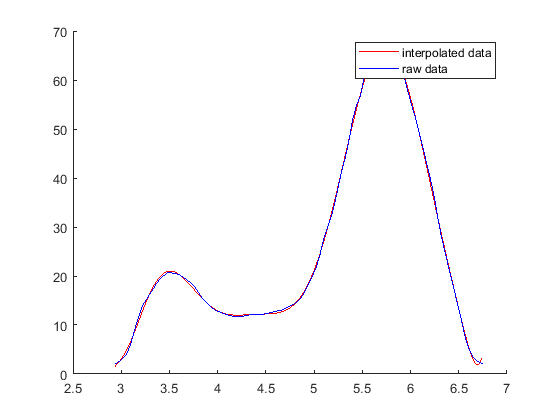

clf
ddata=abs(data(2:end)-data(1));
idx = length(ddata);
[p,S,mu] = polyfit(ts(1:idx),data(1:idx),11);
% tnew = ts(1:idx)';
dtimePoints = 0.02;
tpts = ts(1):dtimePoints:ts(idx);
y1 = polyval(p,tpts,S,mu)*180/pi;
hold on
plot(tpts,y1,'r-',ts,data*180/pi,'b-')
legend('interpolated data','raw data')
hold off

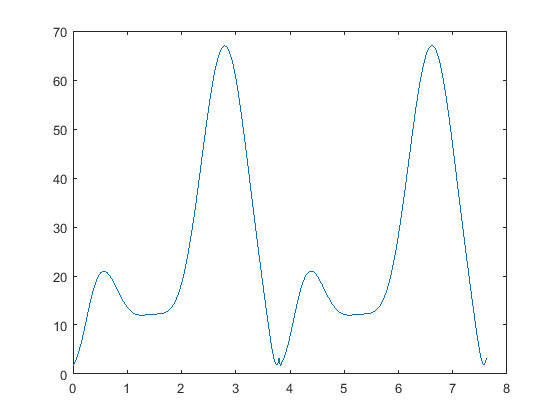

figure
n = 2;
tptsn = 0:dtimePoints:dtimePoints*(length(y1)*n)-dtimePoints;
yn = repmat(y1,1,n);
dyn = diff(yn)/Ts; dyn = [dyn(1) dyn]*4;
ddyn = diff(dyn)/Ts; ddyn = [ddyn(1) ddyn]*4;
plot(tptsn,yn)

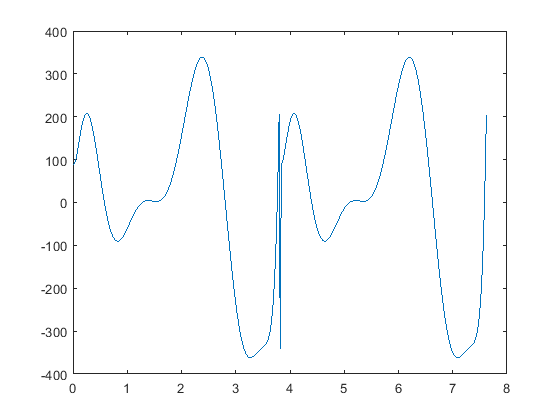

plot(tptsn,dyn)

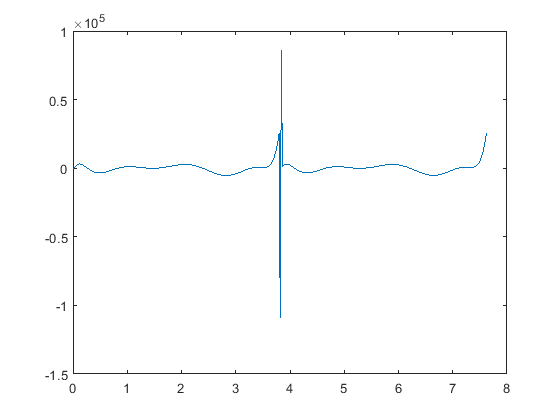

plot(tptsn,ddyn)

switch j
    case 1
        ytime1 = timeseries([yn; dyn; ddyn],tptsn);
    case 2
        ytime2 = timeseries([yn; dyn; ddyn],tptsn);
    case 3
        ytime3 = timeseries([yn; dyn; ddyn],tptsn);
    case 4
        ytime4 = timeseries([yn; dyn; ddyn],tptsn);
end

% 
% 
% 
% ytime4 = timeseries([yn; [1.5 diff(yn)]; [-0.18 -0.18 diff(yn,2)]],tptsn);
% plot(ytime1)

save ytime ytime1 ytime2 ytime3 ytime4

Point trajectory

% cond1 = and(t>=0.5,t<2);
% cond2 = and(t>=2,t<5);
% t1 = t(cond1);
% t2 = t(cond2);
% data1 = tsout.Data(cond1,2);
% data2 = tsout.Data(cond2,2);
% [~,i1] = min(tsout.Data(cond1,2));
% [~,i2] = min(tsout.Data(cond2,2));
% t1 = t1(i1:end);
% t2 = t2(1:i2);
% data1 = data1(i1:end);
% data2 = data2(1:i2);
% ts = [t1; t2];
% data = [data1; data2];
% plot(ts,data,'b.');
% 
% clf
% ddata=abs(data(2:end)-data(1));
% idx = find(ddata==min(ddata));
% [p,S,mu] = polyfit(ts(1:idx),data(1:idx),11);
% % tnew = ts(1:idx)';
% dtimePoints = 0.02;
% tpts = ts(1):dtimePoints:ts(idx);
% y1 = polyval(p,tpts,S,mu)*180/pi;
% hold on
% plot(tpts,y1,'r-',ts,data*180/pi,'b-')
% legend('interpolated data','raw data')
% hold off
% figure
% tmp = diff(y1)/dtimePoints;
% vnew = [-tmp(end)/2 tmp]*2;
% % tmp2 = 2*vnew(163)-vnew(164:end);
% plot(tpts,vnew)
% % plot(tpts,[vnew(1:163) tmp2])
% tmp = diff(vnew)/dtimePoints;
% anew = [tmp(1:end) tmp(end)];
% plot(tpts,anew)

% wpts = y1;
% tvec = tpts(1):Ts:tpts(end);
% [q,qd,qdd,pp] = quinticpolytraj(wpts,tpts,tvec,"VelocityBoundaryCondition",vnew,'AccelerationBoundaryCondition',anew);
% % [q,qd,qdd,pp] = cubicpolytraj(wpts,tpts,tvec,"VelocityBoundaryCondition",vnew);
% plot(tvec, q)
% hold all
% plot(tpts, wpts, 'x')
% xlabel('t')
% ylabel('Positions')
% legend('X-positions')
% hold off
% plot(tvec, qdd)
% xlabel('t')
% ylabel('Velocities')
% legend('angle')